# Placecell clasification from processed event/spike data

This script will take the processed calcium/ behaviour data and calculate if each cell is a placecell or not. It will then calculate ratemaps that can be used for further analysis

### **Prerequisits**

- Behaviour and event data processed via: **"**[**2_Event_processing**](matlab:open('./2_Event_processing.mlx'))**"**

- Data saved as a data structure containing above processed data

### Processing steps

- Open processed data - Open the processed data containing behaviour and calcium events.

- Organsied data -  create a data structure with data needed for place cell classification.

- Check reward zone location -  Check that the reward zones line up with track.

- Place cell classification - Run the place cell classification algorithm.

- Save the data - save the data into a structure. 

## Open processed data file

open the processed data for the animal being analysed

clear all

[session_file save_path] = uigetfile('*','Select session data file');
session_data = importdata(fullfile(save_path,session_file));


Set the id for this analysis by removing the end of the file tag.

analysis_id = erase(session_file,'_calcium_data.mat');


## Organise the data into a structure

create a data structure containing information needed for place cell classificaton

- Coordinates

- Right and Left run logic

- Frame time

- each cells calcium data

Set the names of the sessions (these should match the names in the opened data structure

session_names = ["session_1", "session_2", "session_3"];

data_struct = struct;

for s= 1:size(session_names,2)
session_id = session_names(s);
data_struct.(session_id).track_data.track_cordinates = session_data.(session_id).behave_data.coords.tracked_norm_coords_cms;
data_struct.(session_id).track_data.right_runs = session_data.(session_id).behave_data.runs.right_runs;
data_struct.(session_id).track_data.left_runs = session_data.(session_id).behave_data.runs.left_runs;
data_struct.(session_id).track_data.frame_time = session_data.(session_id).behave_data.frame_time;

data_struct.(session_id).cell_data = session_data.(session_id).cell_data;

end

## Check the reward zone locations 

Check that the **"track_len"** and **"reward_len"** match up to the reward zones on the track image

- use the "rz_bodge" if needed to alter this

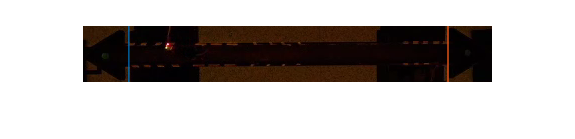

session_id = ["session_2"];

croped_track = session_data.(session_id).behave_data.analysis_vars.norm_outputs.cropped_track;
track_len = 141;
reward_len = 16;
rz_bodge = 1;


check_reward_zone_area(croped_track,track_len,reward_len,rz_bodge);

#### Ensure the lines are equal around the reward zones.

## Run place cell classification

Run the place analysis function "analyse_for_place"

**algorthm steps:**

- **Splits the track into positional bins defined by 'number_bins' variable (usually 40 bins)**

         2. **Analysing left and right traversals seperatly** 

- Count how many events/spikes in each bin

- Calculate time spent in each bin (occupancy)

        3. **Calculate spatial information for cell **

         spaceinfo = (p*(r/rmean))*(log2(r/rmean))

- where:

- p - probability of mouse being in bin

- r - event rate in bin (num spikes / occupancy)

- rmean - average event rate for all bins

          sum spatial info for each bin to get cells spatial information

         4. **Calculate a random spatial information distribution**

- Shuffle the event times and repeat spatial information calculation

- Do this 1000 times to get a random spatial info distribution

          5. **Calculate if spatial info is sig diff from random distribution using z-test**

          6. **For each cell calculate ratemaps**

- Place cells - left and right 

- All cells - left and right

- Unique place cells - (only include ratemaps that have 1 direction place cell)

- Prefered place cells - (if cell has left and right place field keep one with highest rate)


run_perturn = false;

for t = 1:size(session_names,2)
   
    session_id = session_names(t);

    track_data = data_struct.(session_id).track_data;
    cell_data = data_struct.(session_id).cell_data;
    
    % perturbation experiment (delete % events in specific zone) 
    if t == 2 % session 2
        run_perturn = true;
    else
        run_perturn = false;
    end

    [place_cells, rate_maps] = analyse_for_place(track_data,cell_data,'analyse_reward_zone',false,...
                                                                      'reward_zone_len',reward_len,...
                                                                      'eventrate_thresh',2,...
                                                                      'reward_zone_bodge',rz_bodge, ...
                                                                      'number_bins', 40, ...
                                                                      'perturb_bin', run_perturn, ... % set to false if not running perturbation experiments
                                                                      'bin_range_perturb', [10, 18], ...
                                                                      'perturb_scaler', 0.3);
    place_data.(session_id).place_cells_no_rz = place_cells;
    place_data.(session_id).rate_maps_no_rz = rate_maps;

    %package the place data into the oringal file
    session_data.(session_id).place_data_40bins = place_data.(session_id);

end

Analysing right placecells ...please wait
Analysing left placecells ...please wait


## Save the data structure to file

save the new place analysed data


%save_path = uigetdir('');
filetag = "_place_data_40bins_perturb_exp_30";

save(strcat(save_path,'\',analysis_id,filetag,'.mat'),'session_data');

disp(strcat(analysis_id,filetag,'.mat')); disp(strcat("Saved to: ",save_path));

mu85_day2_squ_tri_tri_place_data_40bins_perturb_exp_30.mat
Saved to: M:\Mellor Lab data\Matt Udakis\Data\Inscopix\Experiments\Exp_008_OLM_mcherry\data\mu85\240628_day2_squ_tri_tri\analysed_data\
